# **Práctica 5**

## **Problema 1: Ejemplo 6.2**

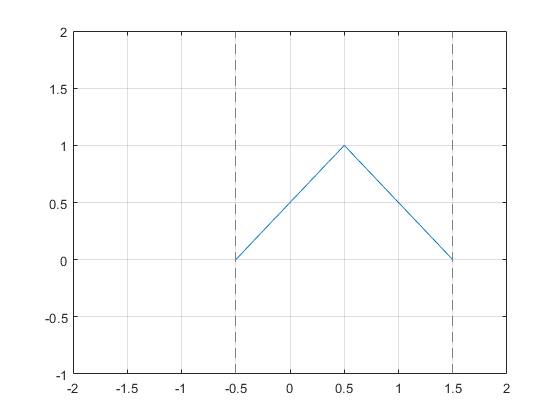

clear all; clc; close all;

syms t n pi ;
assume([n, 'positive', 'integer']);
tr =@(t) piecewise(abs(t)< 1/2,1-2*abs(t));
xt = @(t) tr(((1/2)*(t-(1/2))));

fplot(xt(t));
axis([-2 2 -1 2]);
grid;


T0 = 2;
w0= 2*pi/T0;

Dn = @(n) (1/T0)*int(xt(t)*exp(-n*w0*j*t),t,-1/2, 3/2);
Dn(n)

$$ans = \frac{-4\,{\cos\left(\frac{n\,\pi }{2}\right)}^{3}+4\,\mathrm{i}\,\sin\left(\frac{n\,\pi }{2}\right)\,{\cos\left(\frac{n\,\pi }{2}\right)}^{2}+4\,\cos\left(\frac{n\,\pi }{2}\right)-4\,\sin\left(\frac{n\,\pi }{2}\right)\,\mathrm{i}}{2\,n^{2}\,\pi^{2}}$$

Dn(0)

$$ans = \frac{1}{2}$$

a0 = Dn(0)

$$a0 = \frac{1}{2}$$

an = Dn(n) + Dn(-n)

$$an = \begin{array}{l} \frac{-4\,{\sigma_{2}}^{3}+\sigma_{1}+4\,\sigma_{2}-4\,\sin\left(\frac{n\,\pi }{2}\right)\,\mathrm{i}}{2\,n^{2}\,\pi^{2}}+\frac{-4\,{\sigma_{2}}^{3}-\sigma_{1}+4\,\sigma_{2}+4\,\sin\left(\frac{n\,\pi }{2}\right)\,\mathrm{i}}{2\,n^{2}\,\pi^{2}}\\ \mathrm{where}\\ \sigma_{1}=4\,\mathrm{i}\,\sin\left(\frac{n\,\pi }{2}\right)\,{\sigma_{2}}^{2}\\ \sigma_{2}=\cos\left(\frac{n\,\pi }{2}\right) \end{array}$$

simplify(an, 'Steps', 15)

$$ans = -\frac{4\,\cos\left(\frac{n\,\pi }{2}\right)\,\left({\cos\left(\frac{n\,\pi }{2}\right)}^{2}-1\right)}{n^{2}\,\pi^{2}}$$


bn = (Dn(-n) -Dn(n))/j

$$bn = \begin{array}{l} \frac{\left(-4\,{\sigma_{2}}^{3}+\sigma_{1}+4\,\sigma_{2}-4\,\sin\left(\frac{n\,\pi }{2}\right)\,\mathrm{i}\right)\,\mathrm{i}}{2\,n^{2}\,\pi^{2}}-\frac{\left(-4\,{\sigma_{2}}^{3}-\sigma_{1}+4\,\sigma_{2}+4\,\sin\left(\frac{n\,\pi }{2}\right)\,\mathrm{i}\right)\,\mathrm{i}}{2\,n^{2}\,\pi^{2}}\\ \mathrm{where}\\ \sigma_{1}=4\,\mathrm{i}\,\sin\left(\frac{n\,\pi }{2}\right)\,{\sigma_{2}}^{2}\\ \sigma_{2}=\cos\left(\frac{n\,\pi }{2}\right) \end{array}$$

simplify(bn, 'Steps', 15)

$$ans = \frac{4\,{\sin\left(\frac{n\,\pi }{2}\right)}^{3}}{n^{2}\,\pi^{2}}$$